% This is a generic program to generate plots for Lab #4
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Date: August 6th, 2020
% Dr. Vibhav Durgesh
% Rev 0.0
% User has to provide appropriate information - see beginning of code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all
close all
clc

## Reading the data from appropriate files

fid = fopen('../Data/DynSignal_m500Hz.dat'); %Reading data from the stored file
line1 = fgetl(fid);
data = fscanf(fid,'%f \n', [2 inf]);
time1 = data(1,:);
y1 = data(2,:);
fclose(fid);

fid = fopen('../Data/DynSignal_975Hz.dat'); %Reading data from the stored file
line1 = fgetl(fid);
data = fscanf(fid,'%f \n', [2 inf]);
time2 = data(1,:);
y2 = data(2,:);
fclose(fid);

fid = fopen('../Data/DynSignal_1250Hz.dat'); %Reading data from the stored file
line1 = fgetl(fid);
data = fscanf(fid,'%f \n', [2 inf]);
time3 = data(1,:);
y3 = data(2,:);
fclose(fid);

## Generating figure with specific size

figure (1)
set(gcf,'unit','inches','position',[0.50 0.50 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Creating sup plots

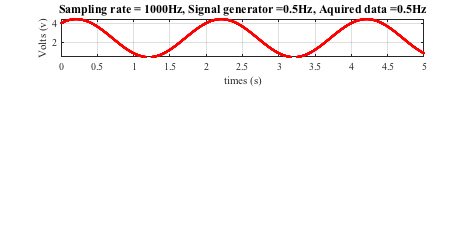

subplot(3,1,1) %% Plotting data for 3 peaks only
plot(time1(1:1:5000),y1(1:1:5000),'r.-','markersize',6,'markerfacecolor','r');hold on
ylim([0.5 4.5])
xlabel('times (s)')
ylabel('Volts (v)')
grid on
title('Sampling rate = 1000Hz, Signal generator =0.5Hz, Aquired data =0.5Hz','fontsize',12)

## Creating sup plots

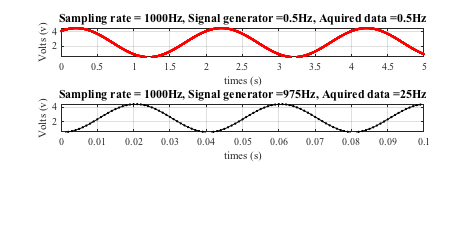

subplot(3,1,2) %% Plotting data for 3 peaks only
plot(time2(1:1:100),y2(1:1:100),'k.-','markersize',6,'markerfacecolor','r');hold on
ylim([0.5 4.5])
xlabel('times (s)')
ylabel('Volts (v)')
grid on
title('Sampling rate = 1000Hz, Signal generator =975Hz, Aquired data =25Hz','fontsize',12)

## Creating sup plots

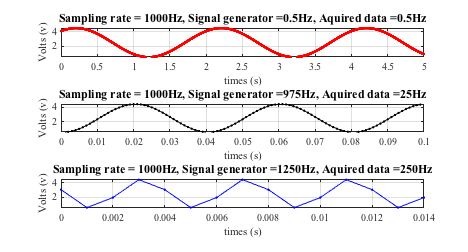

subplot(3,1,3) %% Plotting data for 3 peaks only
plot(time3(1:15),y3(1:15),'b.-','markersize',6,'markerfacecolor','r')
ylim([0.5 4.5])
xlabel('times (s)')
ylabel('Volts (v)')
grid on
title('Sampling rate = 1000Hz, Signal generator =1250Hz, Aquired data =250Hz','fontsize',12)

## Saving the files in png and pdf format

figName = ['../Figures/Student_Name_Exp04_Part2'];
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf,'Position');
set(gcf,'Papersize',figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')